# Centralized

clear;
rng('default');

## Settings

addpath('utils/visualization');
addpath('utils/colors');
addpath('utils/settings');

make_settings("DataType", "condo", "PriceType", "enel")
load('settings.mat');
load('colors.mat');

plotter = Plotter(T);

### Power generation and demand

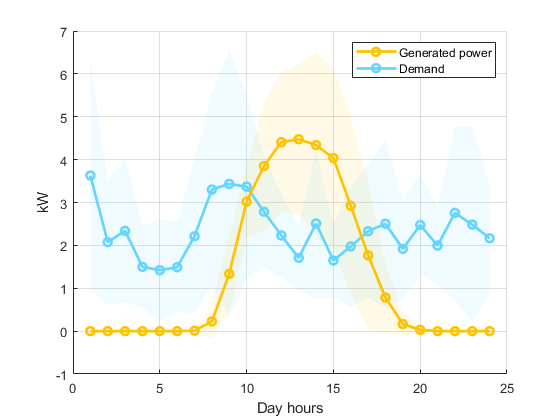

plotter.doublePlot(avg_PV, std_PV, avg_DP, std_DP, 2, 2, "-o", "-o", ...
                   colors.generation, colors.demand, ...
                   "Day hours", "kW", "Generated power", "Demand");

## Optimization problem

% Objective vector
f = [kron(ones(1, P), C) -kron(ones(1, P), R) zeros(1, T*P) zeros(1, T*P) zeros(1, T*P) zeros(1, T*S) zeros(1, T*S) zeros(1, T*S)];

% Objective matrix
H_P = diag([kron(csi, ones(1,T)) kron(csi, ones(1,T)) kron(csi, ones(1,T)) kron(csi, ones(1,T)) zeros(1, T*P)]);
H_S = kron([1 1 0; ...
            1 1 0; ...
            0 0 0], diag(kron(zeta, ones(1,T))));
H = [H_P zeros(5*T*P, 3*T*S);
     zeros(3*T*S, 5*T*P) H_S];

% Equality matrix
k_P = kron(eye(P), [zeros(1,T-1) 1]);
K_P = -eye(T*P) + diag(alpha * ones(1,T*P-1), -1);

K_S = -eye(T*S) + diag(alpha * ones(1,T*S-1), -1);
 
A_1P = [eye(T*P) -eye(T*P) eye(T*P) -eye(T*P) zeros(T*P); 
        zeros(T*P) zeros(T*P) -Eff_dis*eye(T*P) Eff_ch*eye(T*P) K_P; 
        zeros(P,T*P) zeros(P,T*P) zeros(P,T*P) zeros(P,T*P) k_P];

A_1S = [Eff_ch*eye(T*S) -Eff_dis*eye(T*S) K_S];

A_2P = [zeros(T,T*P) zeros(T,T*P) kron(ones(1,P), eye(T)) zeros(T,T*P) zeros(T,T*P);
        zeros(T,T*P) zeros(T,T*P) zeros(T,T*P) kron(ones(1,P), eye(T)) zeros(T,T*P)];

A_2S = [zeros(T,T*S) -kron(ones(1,S), eye(T)) zeros(T,T*S);
        -kron(ones(1,S), eye(T)) zeros(T,T*S) zeros(T,T*S)];

A = [A_1P zeros(P*(2*T+1), 3*S*T);
     zeros(S*T, 5*P*T) A_1S;
     A_2P A_2S];

% Equality vector
a_P = [reshape(DP' - PV', 1, [])';
       kron(s_init', [-alpha; zeros(T-1,1)]);
       s_init'];

a_S = kron(b_init', [-alpha; zeros(T-1,1)]);

a = [a_P; 
     a_S;
     zeros(2*T,1)];

% Inequality matrix 
B_P = kron([1 0 0 0 0; 
            0 1 0 0 0; 
            0 0 1 0 0; 
            0 0 0 1 0], eye(T*P));

B_S = eye(3*S*T);

B = [B_P zeros(4*T*P, 3*T*S);
     zeros(3*S*T, 5*T*P)  B_S];

% Inequality vector 
b_P = [ones(2*T*P, 1) * p_max;
       ones(2*T*P, 1) * d_max];

b_S = [ones(2*T*S, 1) * q_max;
       kron(b_max', ones(T,1))];

b = [b_P;
     b_S];

% Lower bound vector
l = zeros(1, T*(5*P + 3*S));

% Solve the centralized optimization problem
starting_time = tic();
[x, min_cost] = quadprog(H, f, B, b, A, a, l, []);


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


elapsed_time = toc(starting_time)

elapsed_time = 5.5629

## Results

### Gathering variables

x_prosumer = reshape(x(1:5*P*T), T, P, 5);
x_provider = reshape(x(5*P*T+1:end), T, S, 3);

central.var.p_up   = squeeze(x_prosumer(:,:,1))';
central.var.p_down = squeeze(x_prosumer(:,:,2))';
central.var.d_up   = squeeze(x_prosumer(:,:,3))';
central.var.d_down = squeeze(x_prosumer(:,:,4))';
central.var.s      = squeeze(x_prosumer(:,:,5))';

central.var.q_up   = squeeze(x_provider(:,:,1))';
central.var.q_down = squeeze(x_provider(:,:,2))';
central.var.b      = squeeze(x_provider(:,:,3))';

central.var.x = x;

### Gathering parameters

central.par.L = L;
central.par.C = C;
central.par.R = R;
central.par.zeta = zeta;
central.par.csi = csi;

### Power bought

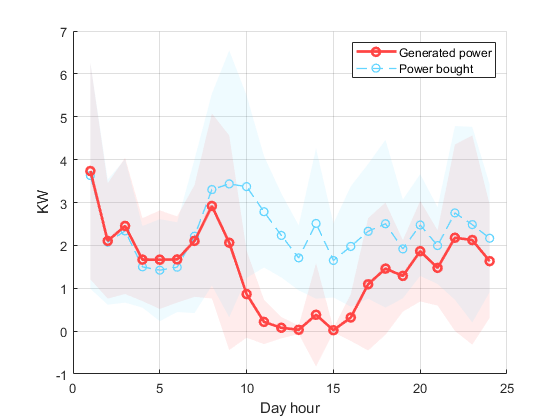

avg_p_up = mean(central.var.p_up, 1);
std_p_up = std(central.var.p_up, 0, 1);

plotter.doublePlot(avg_p_up, std_p_up, avg_DP, std_DP, 2, 1, "-o", "--o", ...
                   colors.retailer, colors.demand, ...
                   "Day hour", "KW", "Generated power", "Power bought");

### Power sold

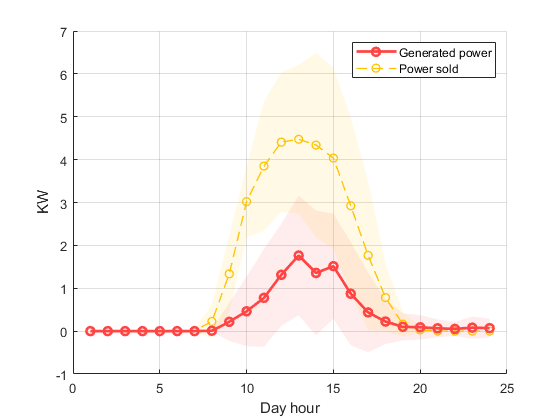

avg_p_down = mean(central.var.p_down, 1);
std_p_down = std(central.var.p_down, 0, 1);

plotter.doublePlot(avg_p_down, std_p_down, avg_PV, std_PV, 2, 1, "-o", "--o", ...
                   colors.retailer, colors.generation, ...
                   "Day hour", "KW", "Generated power", "Power sold");

### Storage and battery state

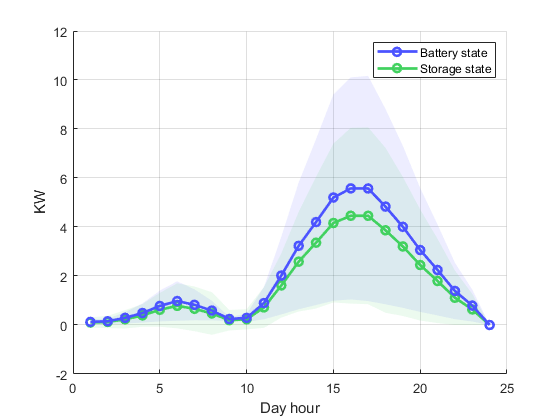

avg_b = mean(central.var.b, 1);
std_b = std(central.var.b, 0, 1);

avg_s = mean(central.var.s, 1);
std_s = std(central.var.s, 0, 1);

plotter.doublePlot(avg_b, std_b, avg_s, std_s, 2, 2, "-o", "-o", ...
                   colors.provider, colors.prosumer, ...
                   "Day hour", "KW", "Battery state", "Storage state");

### Charging and discharging dynamic

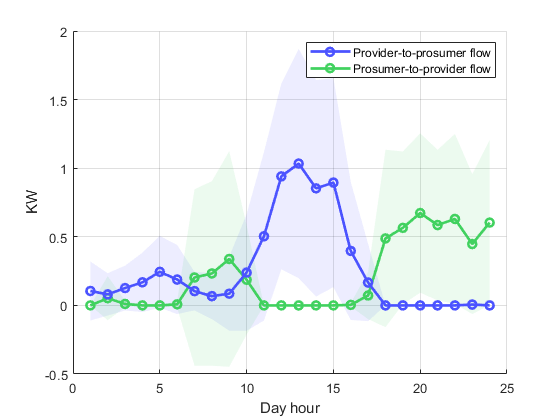

avg_d_down = mean(central.var.d_down, 1);
std_d_down = std(central.var.d_down, 0, 1);

avg_d_up = mean(central.var.d_up, 1);
std_d_up = std(central.var.d_up, 0, 1);

plotter.doublePlot(avg_d_down, std_d_down, avg_d_up, std_d_up, 2, 2, "-o", "-o", ...
                   colors.provider, colors.prosumer, ...
                   "Day hour", "KW", "Provider-to-prosumer flow", "Prosumer-to-provider flow");

### Economy summary

CentralEconomy = economy(central);
CentralEconomyTable = economy_table(CentralEconomy)

CentralEconomyTable = 3×6 table
                 PowerSoldRevenue    PowerBoughtCosts    PowerStoredCosts    PowerStoredRevenues    EfficiencyCosts    TotalCosts
                 ________________    ________________    ________________    ___________________    _______________    __________

    Prosumers         5.0436              21.885              23.559                    0               154.53           194.93  
    Providers              0                   0                   0               23.559               3.8622          -19.697  
    Retailer          5.0436              21.885                   0                    0                    0           16.841  


CommunityTotalCosts = sum(CentralEconomy.Prosumers.TotalCosts) + sum(CentralEconomy.Providers.TotalCosts)

CommunityTotalCosts = 175.2310

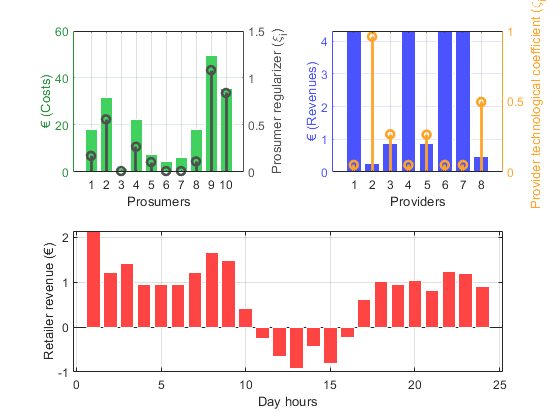


figure;
tiledlayout(2,2)

% Prosumer cost
nexttile;
yyaxis left
ax_pros_cost = gca;
ax_pros_cost.YColor = '#23903a';
bar(CentralEconomy.Prosumers.TotalCosts, ...
    'EdgeColor', 'w', ...
    'FaceColor', colors.prosumer.hex);
ylabel('€ (Costs)');

yyaxis right
ax_csi = gca;
ax_csi.YColor = '#4F4F4F';
stem(csi, ...
     'Color','#4F4F4F', ...
     'LineWidth', 2);
ylabel('Prosumer regularizer (\xi_i)');

grid on;
xlabel('Prosumers');

% Provider revenues
nexttile;
yyaxis left
ax_prov_cost = gca;
ax_prov_cost.YColor = colors.provider.rgb;
bar(-CentralEconomy.Providers.TotalCosts, ...
    'EdgeColor', 'w', ...
    'FaceColor', colors.provider.rgb);
ylabel('€ (Revenues)');

yyaxis right
ax_csi = gca;
ax_csi.YColor = '#FFA326';
stem(zeta, ...
     'Color','#FFA326', ...
     'LineWidth', 2);
ylabel('Provider technological coefficient (\zeta_i)');

grid on; 
xlabel('Providers');

% Retailer revenues
nexttile([1 2]);
bar(CentralEconomy.Retailer.HourlyRevenues, ...
    'EdgeColor', 'w', ...
    'FaceColor', colors.retailer.hex);
grid on;
ylabel('Retailer revenue (€)');
xlabel('Day hours');

### Saving results

central.Economy = CentralEconomy;
save("data/centralized.mat", "central");